## **SIO 207A HW-3**

**Ruipu Ji**

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 11);
set(0, 'DefaultTextFontSize', 11);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

#### I & II. Generation of window functions and plot of window sequences

Different window sequences with a length *N* = 32 are plotted as Figure 1 using the following MATLAB code:

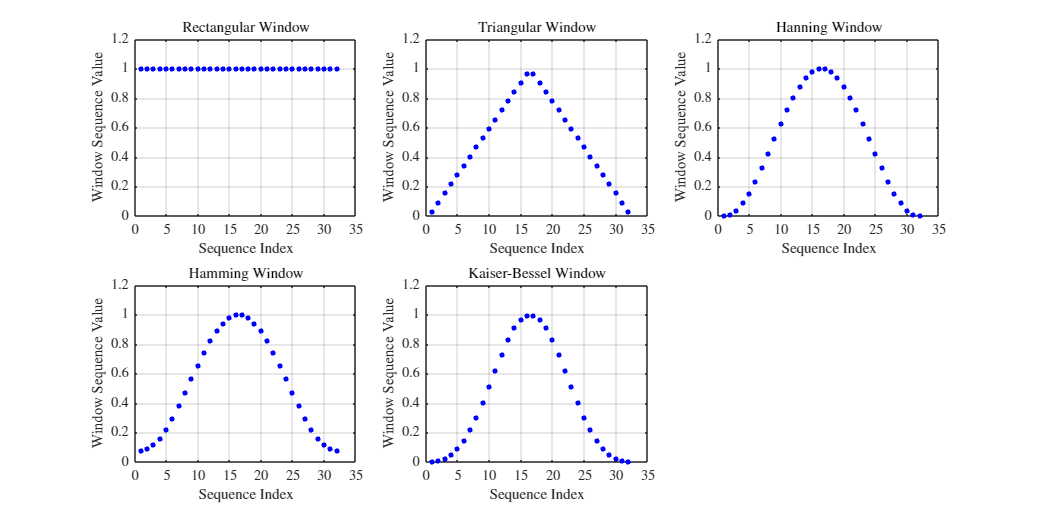

% Define the sequence length.
N = 32;
IndexVector = 1:1:N;

% Generate window sequences with the given sequence length N.
RectangularWindow = rectwin(N); % Rectangular window.
TrangularWindow = triang(N); % Triangular window.
HanningWindow = hann(N); % Hannning window.
HammingWindow = hamming(N); % Hamming window.
KaiserBesselWindow = kaiser(N, 7.85); % Kaiser-Bessel window (alpha = 2.5 or beta = alpha*pi = 7.85).

% Plot each window sequence.
WindowSequences = [RectangularWindow, TrangularWindow, HanningWindow, HammingWindow, KaiserBesselWindow];
Title = {'Rectangular Window', 'Triangular Window', 'Hanning Window', 'Hamming Window', 'Kaiser-Bessel Window'};

figure('Position',[0 0 1200 600]);

for i = 1:size(WindowSequences,2)
    subplot(2,3,i);
    scatter(IndexVector, WindowSequences(:,i), 15, 'o', 'b', 'filled');
    grid on;
    box on;
    xlim([0 35]);
    xticks(0:5:35);
    ylim([0 1.2]);
    yticks(0:0.2:1.2);
    xlabel('Sequence Index');
    ylabel('Window Sequence Value');
    title(Title{i});
end

Figure 1. Plot of different window sequences.

#### III. Polynomial Roots

Considering each of the window sequences in part II as the coefficients of a polynomial, roots of each polynomial are solved and their locations in the complex *z*-plane are plotted in Figure 2 based on the following MATLAB code:

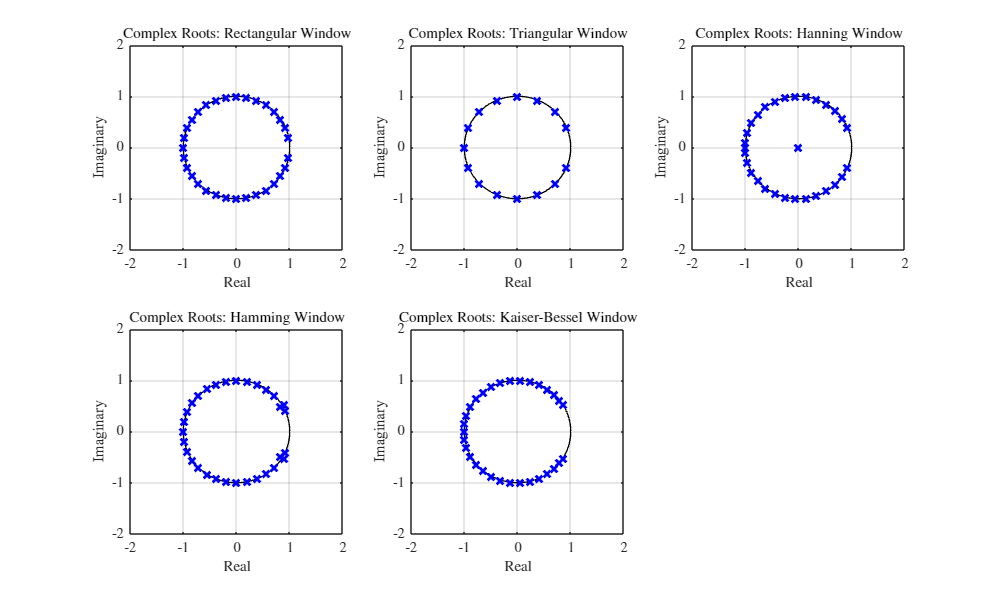

figure('Position',[0 0 1000 600]);

for i = 1:size(WindowSequences,2)
    % Solve the roots of each polynomial based on the coefficients as the window sequences above.
    Roots = roots(WindowSequences(:,i)); 

    subplot(2,3,i);
    hold on;

    % Plot the unit circle.
    theta = linspace(0, 2*pi, 100);
    plot(cos(theta), sin(theta), 'k', 'LineWidth', 1);
    
    % Plot the complex roots.
    plot(real(Roots), imag(Roots), 'x', 'Color', 'b', 'MarkerSize', 7, 'LineWidth', 2);
    
    grid on;
    box on;
    xlim([-2 2]);
    xticks(-2:1:2);
    ylim([-2 2]);
    yticks(-2:1:2);
    xlabel('Real');
    ylabel('Imaginary');
    title(['Complex Roots: ', Title{i}]);
end

Figure 2. Plot of complex root locations for each window sequence.